# Frame Rotation Visualization

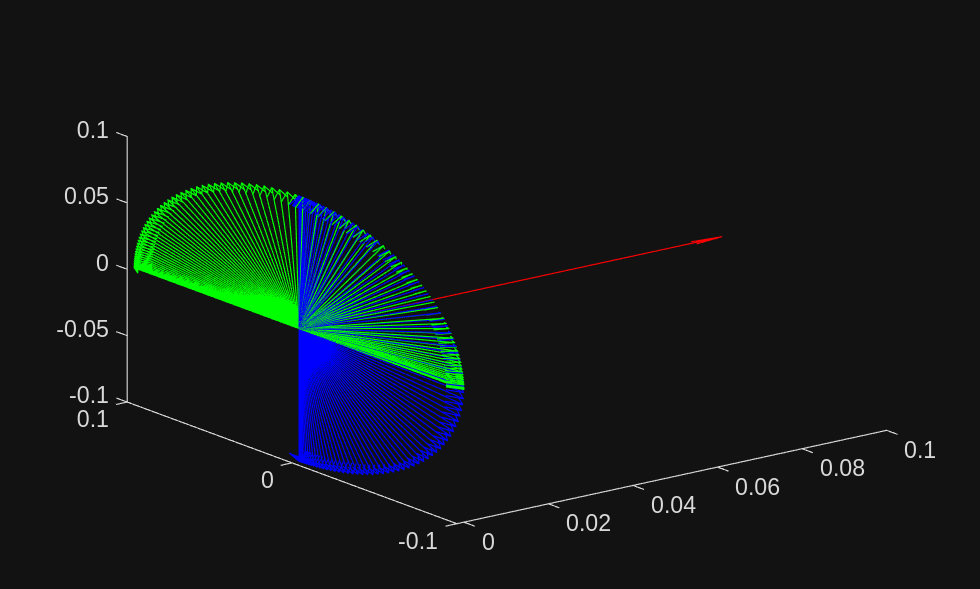

pa = [0 0 0];
qa = quaternion([1 0 0 0]);

pb = [0 0 0];
qb = quaternion([0 1 0 0]);

world = figure;
plot_frame(pa,qa,1);
plot_frame(pb,qb,1);

[Q,Theta,axis,delta_t,theta_coeffs] = cubicAngularTrajectory(qa,0.0,qb,0.0,1);
for i=[1:size(Theta',1)]
    plot_frame(pa,Q(i),1);
end